# Introduction to Drones - 22AIE448

**3D Mapping using a Monocular Camera and Control by Visual-Inertial Odometry (VIO)**

Group CD2 : Ravishanmugam K, Ishwarya Murugesan, Aparna Bharani, Cibikumar B, Akhilan S

School of Artificial Intelligence, Amrita Vishwa Vidyapeetham

**Toy model 3 - Model 1, Part 2 : where am I? The error-state EKF (block 4)**

Run this file with the folder `toy_model3` as the current folder (it uses `DroneLib.m`).

clearvars
clear all
ready = true;
PUBLISH = not(ready);   % make this PUBLISH = ready; to export the file as PDF

clearvars -except PUBLISH ready

## Block 4 - Error-state Extended Kalman Filter

The filter repeats two steps for ever.

- **Predict** : "I know how I pushed the drone, so physics tells me where it should be now." The guess moves forward and the uncertainty **grows**.

- **Correct** : "A sensor reading arrived. How surprised am I?" The guess is pulled towards the measurement, by an amount that depends on whom we trust more. The uncertainty **shrinks**.

It stores the estimate $\hat{x}_k = (\hat{p},\hat{v},\hat{R},\hat{\omega})$ and the covariance $P_k$ (12 x 12) that says how unsure it is about each of the 12 error directions.

**Prediction (time update)**


$$\hat{x}_{k+1} = f_d(\hat{x}_k, u_k) \qquad \rightarrow (10)$$



$$P_{k+1} = F P_k F^T + Q \qquad \rightarrow (11)$$


**Correction (measurement update)**


$$K = P H^T \left(H P H^T + R_n\right)^{-1} \qquad \rightarrow (12)$$



$$\delta\hat{x} = K\left(z - h(\hat{x})\right), \qquad \hat{p} \leftarrow \hat{p} + \delta\hat{p},\ \ \hat{v} \leftarrow \hat{v} + \delta\hat{v},\ \ \hat{R} \leftarrow \hat{R}\,\textrm{Exp}(\delta\hat{\theta}),\ \ \hat{\omega} \leftarrow \hat{\omega} + \delta\hat{\omega} \qquad \rightarrow (13)$$



$$P \leftarrow (I - KH)P \qquad \rightarrow (14)$$


**Where (11) comes from:** $\delta x_{k+1} = F\delta x_k + w_k$, so $E[\delta x_{k+1}\delta x_{k+1}^T] = F\,E[\delta x_k \delta x_k^T]F^T + E[w_k w_k^T] = FP_kF^T + Q$.

**Where (12) comes from:** after the correction the error is $(I-KH)\delta x - Kv$ with covariance $P^+ = (I-KH)P(I-KH)^T + KR_nK^T$. Setting $\partial\,\textrm{trace}(P^+)/\partial K = -2PH^T + 2K(HPH^T + R_n) = 0$ gives (12).

## Toy example - altitude only (scalar filter)

Prior: altitude $\hat{z}_k = 10$ m with variance $P_k = 3.5\textrm{ m}^2$. We command a climb of 0.5 m/s for $\Delta t = 1$ s, $F = 1$, model noise $Q = 0.5$.


$$\hat{z}^- = 10 + 0.5 = 10.5\textrm{ m}, \qquad P^- = 1 \cdot 3.5 \cdot 1 + 0.5 = 4.0\textrm{ m}^2$$


A sensor reads $z = 12.5$ m with variance $R_n = 1\textrm{ m}^2$ and $H = 1$:


$$K = \frac{4}{4 + 1} = 0.8, \qquad \hat{z}^+ = 10.5 + 0.8(12.5 - 10.5) = 12.1\textrm{ m}, \qquad P^+ = (1 - 0.8)\cdot 4 = 0.8\textrm{ m}^2$$


z_hat = 10;  Pk = 3.5;  F = 1;  Q = 0.5;  climb = 0.5;  dt = 1;
z_hat = z_hat + climb*dt          % predict the guess

z_hat = 10.5000

Pk    = F*Pk*F' + Q               % uncertainty grows

Pk = 4

z = 12.5;  H = 1;  Rn = 1;
K     = Pk*H'/(H*Pk*H' + Rn)      % how much to trust the sensor

K = 0.8000

z_hat = z_hat + K*(z - H*z_hat)   % corrected guess

z_hat = 12.1000

Pk    = (1 - K*H)*Pk              % uncertainty shrinks

Pk = 0.8000

The sensor is 4 times more trustworthy than the prediction ($P^-/R_n = 4$), so the estimate moves 80 % of the way towards it.

## The full 12-state filter on the drone

**The truth.** The drone flies a climbing helix in gusty wind. To create it we fly the simulator with the SO(3) controller of block 5-8 (file M1_3) using the **true** state. The filter never sees the truth; it only sees the commands $u_k$ and noisy sensors.

clearvars -except PUBLISH ready
P  = DroneLib.params();
rng(4);
dt = 0.01;  t = 0:dt:20;  N = numel(t);      % 100 Hz IMU, 20 s
X = zeros(18, N);  U = zeros(4, N);
X(:,1) = DroneLib.pack([0.3;-0.3;1.8], zeros(3,1), eye(3), zeros(3,1));
for k = 1:N
    [p, v, R, w] = DroneLib.unpack(X(:,k));
    u = DroneLib.so3_control(p, v, R, w, DroneLib.helix(t(k)), P);
    [~, ~, U(:,k)] = DroneLib.mixer(u, P);
    if k < N
        gust = [0.2*randn(3,1); 5e-4*randn(3,1)];         % wind force, torque
        X(:,k+1) = DroneLib.rk4(X(:,k), U(:,k), dt, P, gust);
    end
end

**The sensors** (tilde = measured):

- gyroscope, 100 Hz : $\tilde{\omega} = \omega + \textrm{noise}$ ($\sigma$ = 0.01 rad/s)

- monocular camera through visual odometry, 25 Hz : $\tilde{p}$ ($\sigma$ = 5 cm) and $\tilde{R}$ ($\sigma$ = 0.02 rad)


$$H_{gyro} = \left[\begin{array}{cccc} 0 & 0 & 0 & I \end{array}\right], \qquad H_{cam} = \left[\begin{array}{cccc} I & 0 & 0 & 0\\ 0 & 0 & I & 0 \end{array}\right]$$


The velocity is **never measured**; the filter works it out from the physics.

sig_p = 0.05;  sig_th = 0.02;  sig_g = 0.01;
Zp = zeros(3,N);  Zth = zeros(3,N);  Zg = zeros(3,N);
for k = 1:N
    [p, ~, R, w] = DroneLib.unpack(X(:,k));
    Zp(:,k)  = p + sig_p*randn(3,1);
    Zth(:,k) = DroneLib.logSO3(R*DroneLib.expSO3(sig_th*randn(3,1)));
    Zg(:,k)  = w + sig_g*randn(3,1);
end
Hg = [zeros(3,9) eye(3)];
Hc = [eye(3) zeros(3,9); zeros(3,6) eye(3) zeros(3,3)];
Rg = sig_g^2*eye(3);
Rc = blkdiag(sig_p^2*eye(3), sig_th^2*eye(3));
Q  = blkdiag(1e-8*eye(3), (0.2/P.m*dt)^2*eye(3), 1e-8*eye(3), (5e-4/P.J(1,1)*dt)^2*eye(3));

**Run the filter**, starting from a wrong guess (30 cm, 0.2 m/s and about 7 degrees off):

[p0, v0, R0, w0] = DroneLib.unpack(X(:,1));
xh = DroneLib.pack(p0 + [0.3;-0.2;0.1], v0 + [0.2;-0.1;0.1], R0*DroneLib.expSO3([0.05;-0.05;0.1]), w0);
Pk = blkdiag(0.3^2*eye(3), 0.2^2*eye(3), 0.1^2*eye(3), 0.05^2*eye(3));
Xh = zeros(18,N);  Err = zeros(12,N);  Sig = zeros(12,N);
for k = 1:N
    [~, ~, ~, wh] = DroneLib.unpack(xh);                       % gyro correction
    [xh, Pk] = DroneLib.ekf_update(xh, Pk, Zg(:,k) - wh, Hg, Rg);
    if mod(k-1, 4) == 0                                        % camera correction (25 Hz)
        [ph, ~, Rh] = DroneLib.unpack(xh);
        r = [Zp(:,k) - ph; DroneLib.logSO3(Rh'*DroneLib.expSO3(Zth(:,k)))];
        [xh, Pk] = DroneLib.ekf_update(xh, Pk, r, Hc, Rc);
    end
    Xh(:,k) = xh;  Sig(:,k) = sqrt(diag(Pk));
    Err(:,k) = DroneLib.boxminus(X(:,k), xh);
    if k < N                                                   % prediction
        [xh, Pk] = DroneLib.ekf_predict(xh, Pk, U(:,k), dt, P, Q);
    end
end

**Accuracy** (after the first 2 s):

s = t > 2;
rms3 = @(rows) sqrt(mean(sum(Err(rows, s).^2, 1)));
raw  = Zp(:, 1:4:end) - X(1:3, 1:4:end);
position_cm      = 100*rms3(1:3)

position_cm = 2.5509

raw_camera_cm    = 100*sqrt(mean(sum(raw.^2, 1)))

raw_camera_cm = 8.5493

velocity_cm_s    = 100*rms3(4:6)

velocity_cm_s = 3.8503

attitude_deg     = rad2deg(rms3(7:9))

attitude_deg = 0.2024

inside_3sigma_pc = 100*mean(all(abs(Err(:, s)) <= 3*Sig(:, s), 1))

inside_3sigma_pc = 99

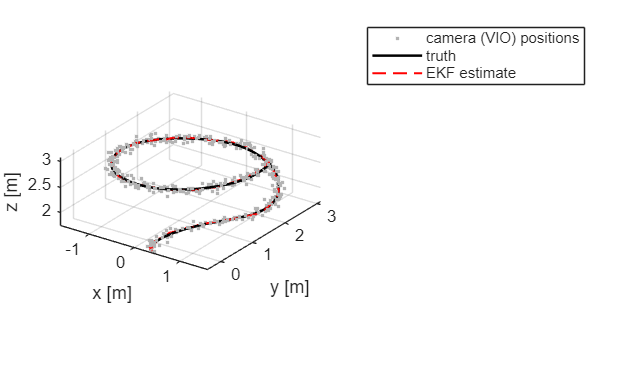

figure
plot3(Zp(1,1:4:end), Zp(2,1:4:end), Zp(3,1:4:end), '.', Color=[0.7 0.7 0.7]); hold on
plot3(X(1,:), X(2,:), X(3,:), 'k', LineWidth=1.5)
plot3(Xh(1,:), Xh(2,:), Xh(3,:), 'r--', LineWidth=1.2); hold off
grid on; axis equal; view(35, 25)
xlabel("x [m]"); ylabel("y [m]"); zlabel("z [m]")
legend("camera (VIO) positions", "truth", "EKF estimate")

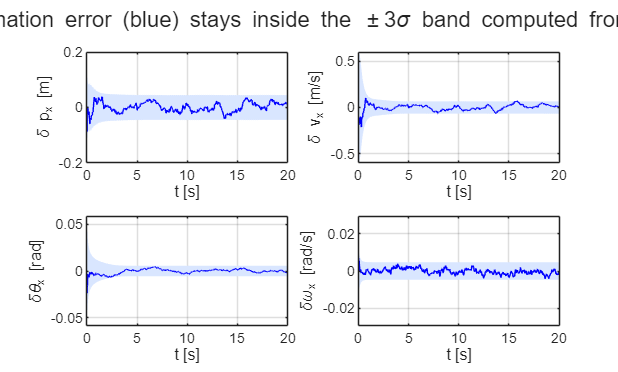

figure
names = ["\delta p_x [m]", "\delta v_x [m/s]", "\delta\theta_x [rad]", "\delta\omega_x [rad/s]"];
rows  = [1 4 7 10];
for i = 1:4
    subplot(2,2,i)
    fill([t fliplr(t)], [3*Sig(rows(i),:) -fliplr(3*Sig(rows(i),:))], [0.85 0.9 1], EdgeColor="none"); hold on
    plot(t, Err(rows(i),:), 'b'); hold off; grid on
    xlabel("t [s]"); ylabel(names(i))
end
sgtitle("Estimation error (blue) stays inside the \pm3\sigma band computed from P_k")

**In the real drone:** this is the "VIO" of our title. A monocular camera alone cannot tell scale and an IMU alone drifts within seconds; the EKF fuses them with the physics. In our SITL set-up ArduPilot's own EKF3 runs this structure and publishes the result on `/ap/v1/pose/filtered` and `/ap/v1/twist/filtered`, which `controller_node.py` reads in `pose_callback` and `twist_callback`. Our VIO pipeline provides the camera measurement $z_{cam}$.

if(PUBLISH == ready)
    mlxfile = matlab.desktop.editor.getActive().Filename;
    [folder, name, ext] = fileparts(mlxfile);
    outfilepdf = fullfile(folder, 'pdf', [name, ext, '.pdf']);
    export(mlxfile, outfilepdf);
    if ispc
        winopen(outfilepdf);
    elseif ismac
        system(['open ' char(outfilepdf)]);
    else
        system("env -u LD_LIBRARY_PATH xdg-open '" + outfilepdf + "' &");
    end
end